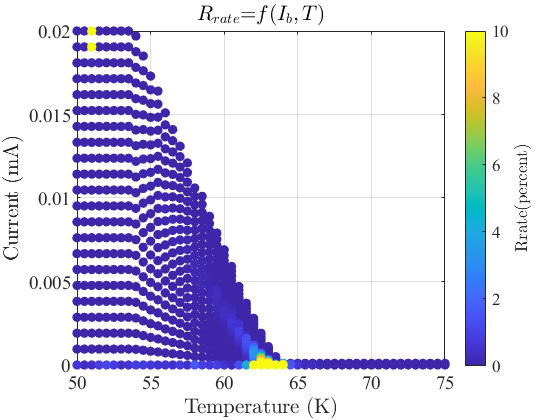

clear;clf("reset"); clc;
Path = 'M:\20230627\415-4-4\CurrStep'; % Folder path of series test data
File = dir(fullfile(Path,'*.mat')); % Extract all .mat files in the folder
FileNames = {File.name}';
load([Path, '\', FileNames{1}])
len = length(FileNames);
pat = regexpPattern('\d+.\d+K');
dataM = [];
for i = 1:len
    load([Path, '\', FileNames{i}])
    Reresult = extract(FileNames{i},pat);
    Temp = str2double(Reresult{1}(1:end-1));
    [sourceList, Rrate, VppList] = currentStepSweep(volt, curr, t);
%     sourceList = sourceList/max(sourceList);
    TList = Temp*ones(length(sourceList),1);
    addMat = [TList,sourceList', Rrate',VppList'];
    dataM = [dataM;addMat];
end
scatter3(dataM(:,1),dataM(:,2),dataM(:,3),50,dataM(:,3),"filled")
view([0 90.0]);caxis([0 10]);box on;xlim([50 75])
title('$R_{rate}$=$f(I_b,T)$',"Interpreter","latex");
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Current (mA)',"Interpreter","latex");
% ylabel('$I_b/I_c$',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
%set(gca,'YScale','log') % This line for LogScale Current Sweep
c = colorbar; c.Label.String = 'Rrate(percent)';
c.Label.Interpreter = 'latex';

function [sourceList, Rrate, VppList] = currentStepSweep(volt, curr, t)
time = t; source = curr;
if min(diff(time))<0
    t_stop_idx = find(diff(time)<0);
    v = data(1:t_stop_idx,4);
    c = data(1:t_stop_idx,5);
    s = data(1:t_stop_idx,7);
    t = data(1:t_stop_idx,6);
    time = linspace(t(1),t(end),size(t,1));
    volt = interp1(t,v,time);
    curr = interp1(t,c,time);
    source = interp1(t,s,time,"next");
else
    t = time;
    time = linspace(time(1),time(end),size(time,2));
    volt = interp1(t,volt,time);
    curr = interp1(t,curr,time);
    source = interp1(t,source,time,"next");
end

[d_volt, rmind] = rmoutliers(diff(volt)./diff(time));

% f1 = figure(1);f1.Position(3:4) = [560 700]; 
% subplot(311);
% [AX,Ha,Hb] = plotyy(time(~rmind),d_volt/(2*pi),time,source);
% set(get(AX(1),'ylabel'),'string','$ d(volt)/(dt\cdot2\pi) $','interpreter','latex');
% set(get(AX(2),'ylabel'),'string','source (A)','interpreter','latex');
% subplot(312);
time_diff = time(~rmind);
wt_volt = interp1(time_diff,d_volt,time,"makima");
[cfs,frq] = cwt(wt_volt, 1/mean(diff(time)));
% surface(time,frq,abs(cfs));axis tight;shading flat
% ylim([0.1,2])
% xlabel('Time (s)','Interpreter',"latex");
% ylabel('Freq (Hz)',"Interpreter","latex");
% subplot(313);
% plot(time,1e3*wt_volt/(2*pi),time,1e3*abs(cfs(46,:))/(2*pi));
% xlabel('Time (s)','Interpreter',"latex");
% ylabel('Vpp (mV)',"Interpreter","latex");

% f2 = figure(2);f2.Position(3:4) = [560 700]; 
volt_rmbg = volt-[0, cumsum(diff(volt).*double(rmind))];
[pks, plocs] = findpeaks(volt_rmbg);
[vas, vlocs] = findpeaks(-volt_rmbg);
% subplot(311);
% plot(time,volt_rmbg);hold on
% scatter(time(plocs),pks);
% scatter(time(vlocs),-vas);hold off
% xlabel('Time (s)','Interpreter',"latex");
% ylabel('Signal (V)',"Interpreter","latex");
idx = min(size(plocs,2),size(vlocs,2));
vpp = (pks(1:idx-2)+pks(2:idx-1))/2+vas(1:idx-2);
% subplot(312);
leakage_rate = 0.5;
% plot(time,5*abs(cfs(47,:))/(2*pi)/(leakage_rate),'.', ...
%     time(vlocs(1:idx-2)),vpp,'o--');
% xlabel('Time (s)','Interpreter',"latex");
% ylabel('Vpp (V)',"Interpreter","latex");
% subplot(313);
vpp_cwt = 5*abs(cfs(47,:))/(2*pi)/(leakage_rate);
delta_R = vpp_cwt./curr;
R = volt./curr;
delta_R_rate = delta_R./R;
% plot(time,delta_R_rate*100,'.');
% xlabel('Time (s)','Interpreter',"latex");
% ylabel('$ \Delta R/R $ (\%)',"Interpreter","latex");
% f3 = figure(3);f3.Position(3:4) = [560 700]; 
[G, Bias_curr] = findgroups(source);
DeltaR_mean = splitapply(@mean,delta_R,G);
Vpp_mean = splitapply(@mean,vpp_cwt,G);
Rrate_mean = splitapply(@mean,delta_R_rate,G);
T = table(Bias_curr',Vpp_mean',DeltaR_mean',100*Rrate_mean');
T.Properties.VariableNames = ["I_bias","Vpp","DeltaR","R_rate"];
% subplot(311);
% boxplot(1e3*vpp_cwt,source*1e3);
% xlabel('Bias Current (mA)',"Interpreter","latex");
% ylabel('Vpp (mV)',"Interpreter","latex")
% subplot(312);
% boxplot(1e3*R,source*1e3);
% xlabel('Bias Current (mA)',"Interpreter","latex");
% ylabel('$ \Delta R $ ($\Omega$)',"Interpreter","latex")
% subplot(313);
% boxplot(1e2*delta_R_rate,source*1e3);ylim([0,30])
% xlabel('Bias Current (mA)',"Interpreter","latex");
% ylabel('$ \Delta R/R $ (\%)',"Interpreter","latex")
sourceList = Bias_curr;
Rrate = 100*Rrate_mean;
VppList = Vpp_mean;
end